Nombre: Alfredo Robledano Abasolo

Fecha: 15-02-2023

# Ejercicio T2.B2

clc
clear

a) (6p) Crea una función en MATLAB que calcule la raíz de una función dada en forma anónima y = @(x) mediante el método de la bisección. Nómbrala de la siguiente forma:

function [xs, i] = biseccion(y,a,b,ermax)

a) Véase biseccion.m

b) (4p) calcular la raíz de la función 


$$f\left(x\right)=x^3 -2\textrm{sen}\left(x\right)$$


Con un error máximo de 1e-5

b)

f = @(x) x.^3 - 2.*sin(x);
ermax = 1e-5;

Dibujamos la gráfica de la función para encontrar un intervalo de búsqueda.

x = linspace(0, 2);
plot(x, f(x))

Observamos que para calcular la raiz un buen intervalo puede ser el (1, 1.5).

hold on
yline(0, '-', 'x')
a = 1;
b = 1.5;
[x0, i] = biseccion(f, a, b, ermax);
fprintf("Una de las raices de f(x) es:\n%.6f", x0)

Una de las raices de f(x) es:
1.236183

fprintf("Se han requerido %d iteraciones.", i);

Se han requerido 16 iteraciones.

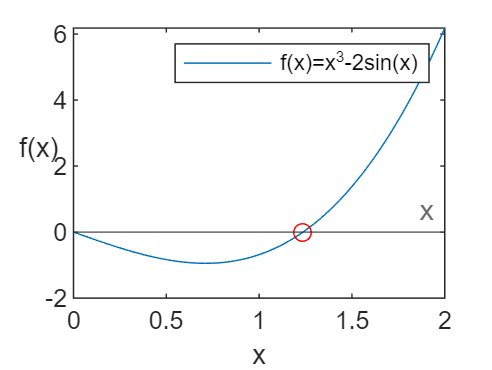

plot(x0, f(x0), 'ro');
xlabel('x')
ylabel('f(x)', Rotation=0)
legend('f(x)=x^{3}-2sin(x)')
hold off

Comprueba el resultado con la función fzero de Matlab calculando el error relativo porcentual tomando como valor real el obtenido mediante la función de Matlab. 

x0_matlab = fzero(f, [a, b]);
fprintf("La solucion que da matlab con 6 decimales es:\n%.6f", x0_matlab)

La solucion que da matlab con 6 decimales es:
1.236184

er_rel = abs((x0_matlab - x0) / x0_matlab);
fprintf("El error relativo porcentual es:\n%.6f %%", er_rel*100)

El error relativo porcentual es:
0.000062 %

Comprueba que se cumple la relación teórica entre el número de iteraciones y el error máximo. (ver apuntes)

Sabemos que el número de iteraciones se relaciona con el error según la siguiente expresión.


$$n>\frac{\ln \left(\frac{b-a}{E}\right)}{\ln \;2}$$


n = log((b-a)/ermax) / log(2);
disp("Calculando el numero de iteraciones de manera teorica se obtiene:")

Calculando el numero de iteraciones de manera teorica se obtiene:


fprintf("%.2f ~ %d", n, round(n))

15.61 ~ 16

if i == round(n)
    disp("Se cumple la relación teórica entre el número de iteraciones y el error máximo.")
else
    disp("No se cumple la relación teórica entre el número de iteraciones y el error máximo.")
end

Se cumple la relación teórica entre el número de iteraciones y el error máximo.
